Projet Tutoré Académique

# Simulation d'une Machine Assynchone Triphasée à Cage

# e son contrôle de vitesse

ENSEM 3A - Bureau d'énergie 

09/02/24

Étudiant : SALES Déric 

clc; clear all; close all;

% Changer le dossier actuel pour l'endroit où se trouve le fichier MATLAB actuel
if(~isdeployed)
    path = fileparts(matlab.desktop.editor.getActiveFilename);
  cd(path);
end

## Paramètres phisiques de la machine

Ls = 210e-6;  % Inductance du stator, en henrys
Lr = Ls;  % Inductance du rotor, en henrys
M = 195.5e-6;  % Inductance mutuelle entre le stator et le rotor, en henrys
Rr = 4.5e-3;  % Résistance du rotor, en ohms
Rs = 3e-3;  % Résistance du stator, en ohms
p = 2;  % Nombre de pôles du moteur
f = 5.5e-3;  % coeficient de frottement
J = 10.8e-3;  % moment d'inertie du rotor de la machine

taur = Lr/Rr; % constante de temps rotorique
sigma = 1 - (M^2)/(Ls*Lr) % efficacité de la conversion d'énergie 

sigma = 0.1333

Descriptive plus detailée des variables:

- J $\rightarrow$ Moment d'inertie du rotor, en kg.m². C'est une mesure de la résistance du rotor au changement de vitesse de rotation.

- Ls $\rightarrow$ Inductance du stator, en henrys. Cela représente la capacité du stator à stocker de l'énergie sous forme de champ magnétique.

- Lr = Ls $\rightarrow$ Inductance du rotor, en henrys. On suppose ici que l'inductance du rotor est égale à celle du stator.

- M $\rightarrow$ Inductance mutuelle entre le stator et le rotor, en henrys. Ceci mesure l'efficacité du couplage magnétique entre le stator et le rotor.

- Rr $\rightarrow$ Résistance du rotor, en ohms. Cela représente les pertes électriques dans le rotor dues à sa résistance.

- Rs $\rightarrow$ Résistance du stator, en ohms. Similaire à Rr, mais pour le stator.

- p $\rightarrow$ Nombre de pôles du moteur. Cela affecte la vitesse de rotation synchrone du moteur.

- f $\rightarrow$ Coefficient de frottement. Cela représente les pertes mécaniques dues au frottement.

- R $\rightarrow$ Matrice de résistance avec des valeurs négatives pour la formulation des équations différentielles.

- ML $\rightarrow$ Matrice d'inductance incluant l'inductance propre et mutuelle.

## Controlêur

### Matrices de transformations

Transformation de Concordia-Park :

T_23 = sqrt(2/3)*[1 -1/2 -1/2;  0  sqrt(3)/2 -sqrt(3)/2];
T_32 = T_23';

### Paramètres

Kp2 = 0.0207;
tau2 = 0.0041; % controleur des tentions d'entrée a partir des currents

Kp3 = 1;
tau3 = 1; % Eq.couple, controleur de current a partir de la vitesse

### Calcul coefitients du controleur 

Req = Rs + ((Ls/taur)*(1 - sigma)) ; 

sigma = 0.1333

Leq = sigma*Ls;

syms s Kp

tau_eq = Leq/Req;
FTmas = (1/Req)/(1+ s*tau_eq);

faisant $\tau_i = \tau_{eq}$ et $K_p = 3  R_{eq}$ 

tau_i = tau_eq

tau_i = 0.0041

Kp = 3*Req

Kp = 0.0207

FTpi = Kp*(1 + tau_i*s)/(tau_i*s);
FTbo = FTpi*FTmas;
FTbf = FTbo/(1 + FTbo);

FTbo = simplify(FTbo)

$$FTbo = \frac{4346230629353929536436143584421}{5878687615375127227041579008\,s}$$

FTbf = simplify(FTbf)

$$FTbf = \frac{4346230629353929536436143584421}{5878687615375127227041579008\,s+4346230629353929536436143584421}$$

## Exécution de la simulation

Définition des paramètres de la simulation :

start_time = 0.0;
stop_time = 30.0;
fixed_step_size = 1e-4;

Execution de la simulation :

%sim('MAS7');

Effacer des variables dans l'espace de travail

% axe du temps
t = start_time:fixed_step_size:stop_time;

% List all variables in the base workspace
vars = evalin('base', 'who');

% Identify variables to keep
varsToKeep = {'ans', 't', 'path' };

% Identify variables to clear
varsToClear = setdiff(vars, varsToKeep);

% Clear the variables except for those in varsToKeep
clear(varsToClear{:});

clear vars varsToClear varsToKeep

## Récuperation des données de la simulation

% ficher pour souvegarder les images des simulaitons
clear saving_folder
saving_folder = 'simuImgs';
saving_folder = fullfile(path,saving_folder);

#### vitesse de rotation du rotor de la machine

wm = ans.wm;

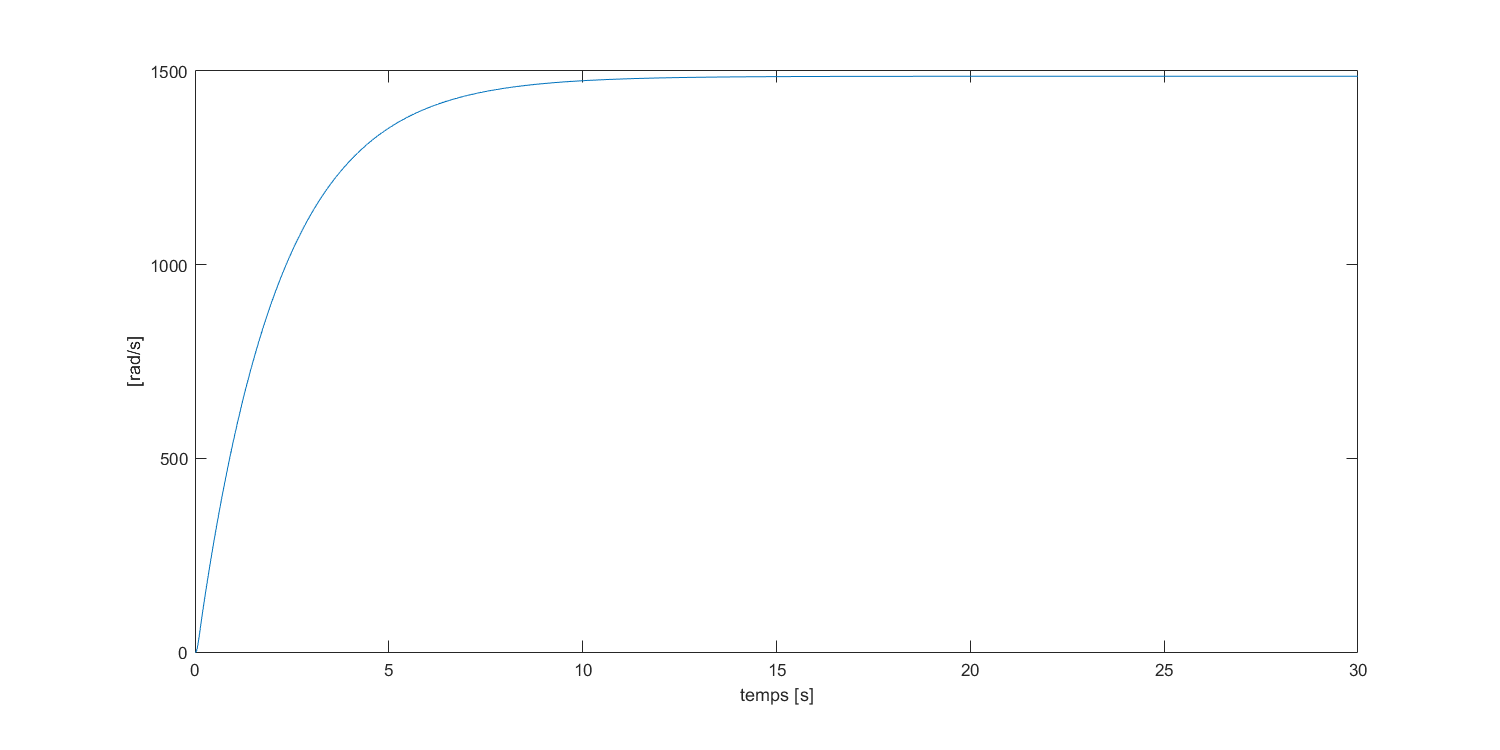

figure;
plot(t,wm); 
xlabel("temps [s]");
ylabel("[rad/s]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'wm.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### courant triphasées du stator

is_abc = ans.is_abc;

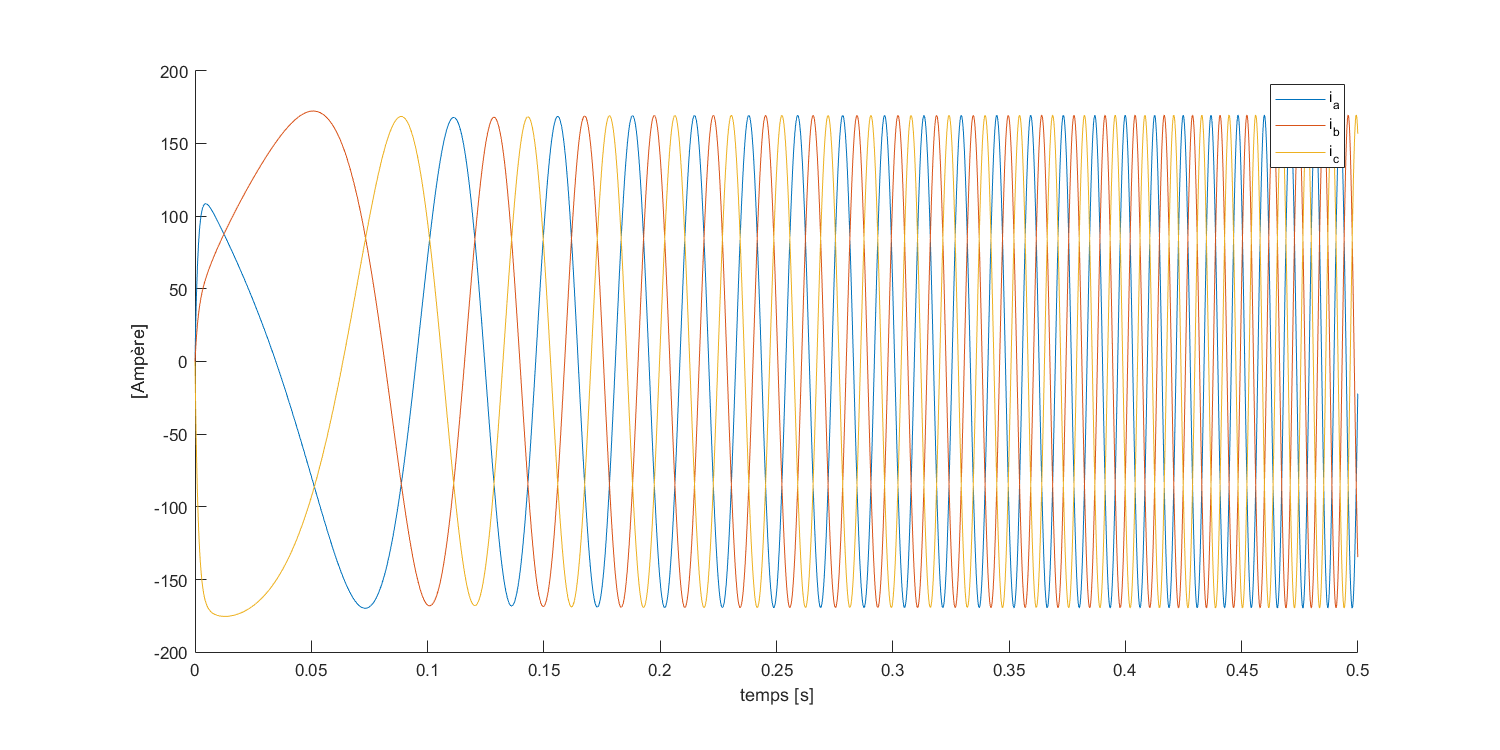

figure;
hold on;
plot(t(1:1e4/2),is_abc(1:1e4/2,1), 'DisplayName', 'i_a'); 
plot(t(1:1e4/2),is_abc(1:1e4/2,2), 'DisplayName', 'i_b'); 
plot(t(1:1e4/2),is_abc(1:1e4/2,3), 'DisplayName', 'i_c'); 
legend()
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'is_abc.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### puissance de la machine 3f

P = ans.P;

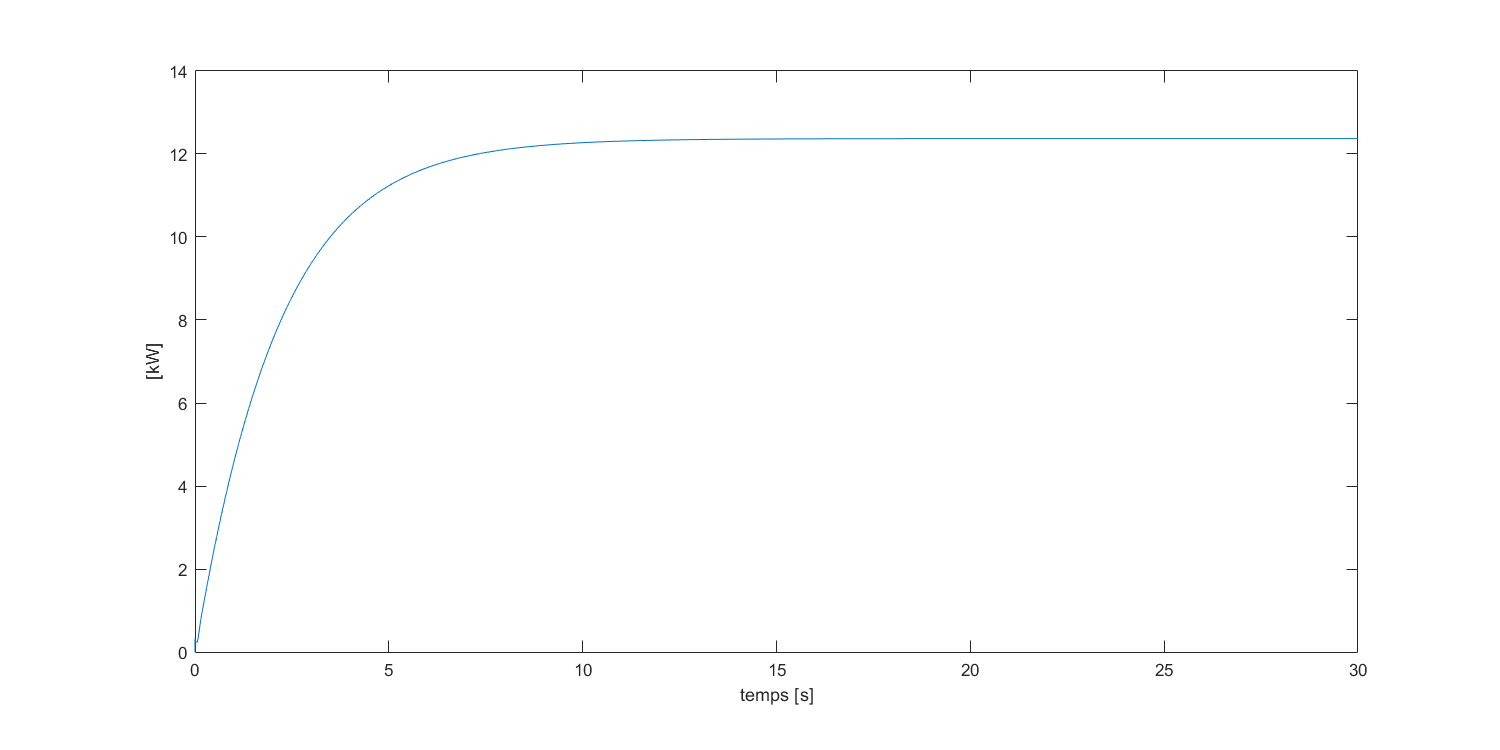

figure;
plot(t,P/1e3); 
xlabel("temps [s]");
ylabel("[kW]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'P.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### puissance de la machine 2f

Pdq = ans.Pdq;

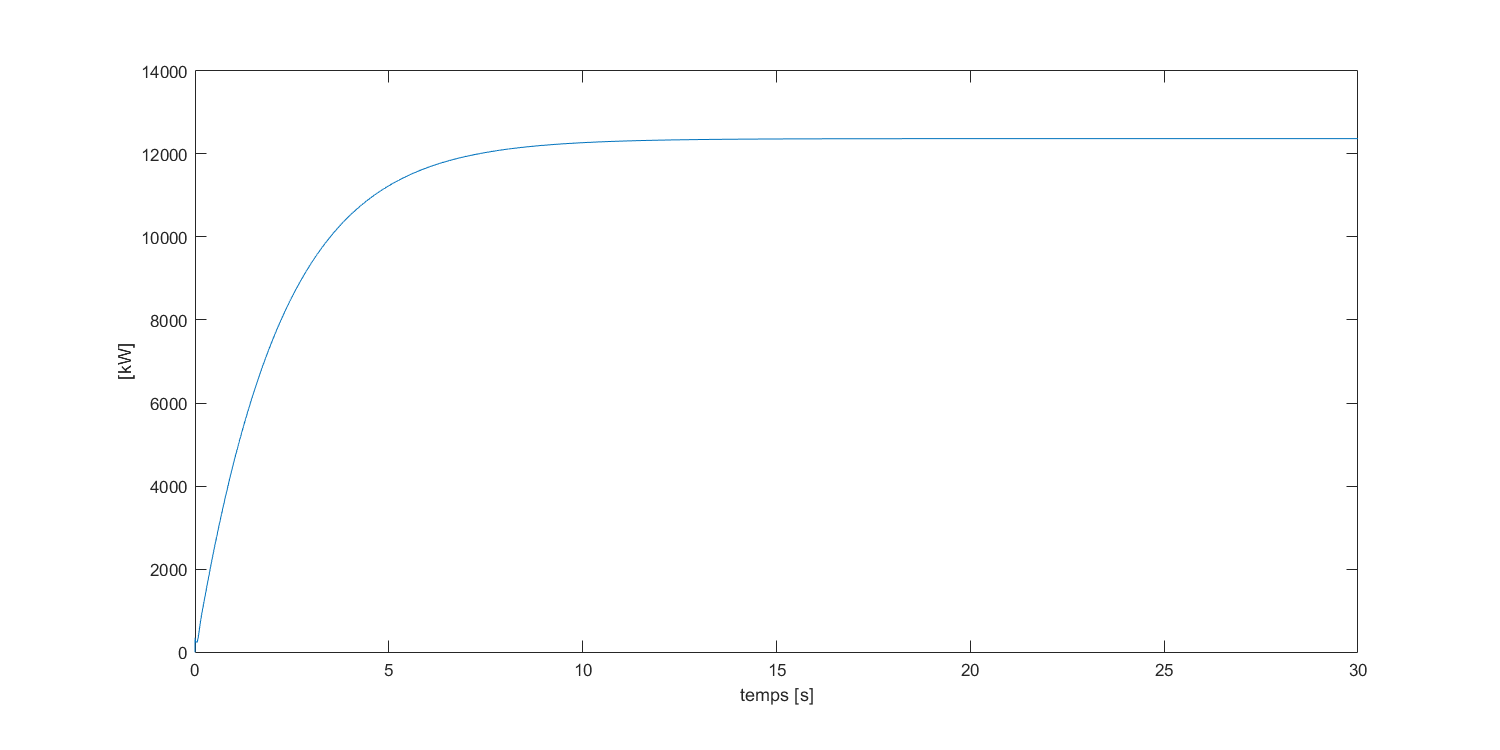

figure;
plot(t,Pdq); 
xlabel("temps [s]");
ylabel("[W]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'Pdq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### torque de la machine

torque = ans.torque;

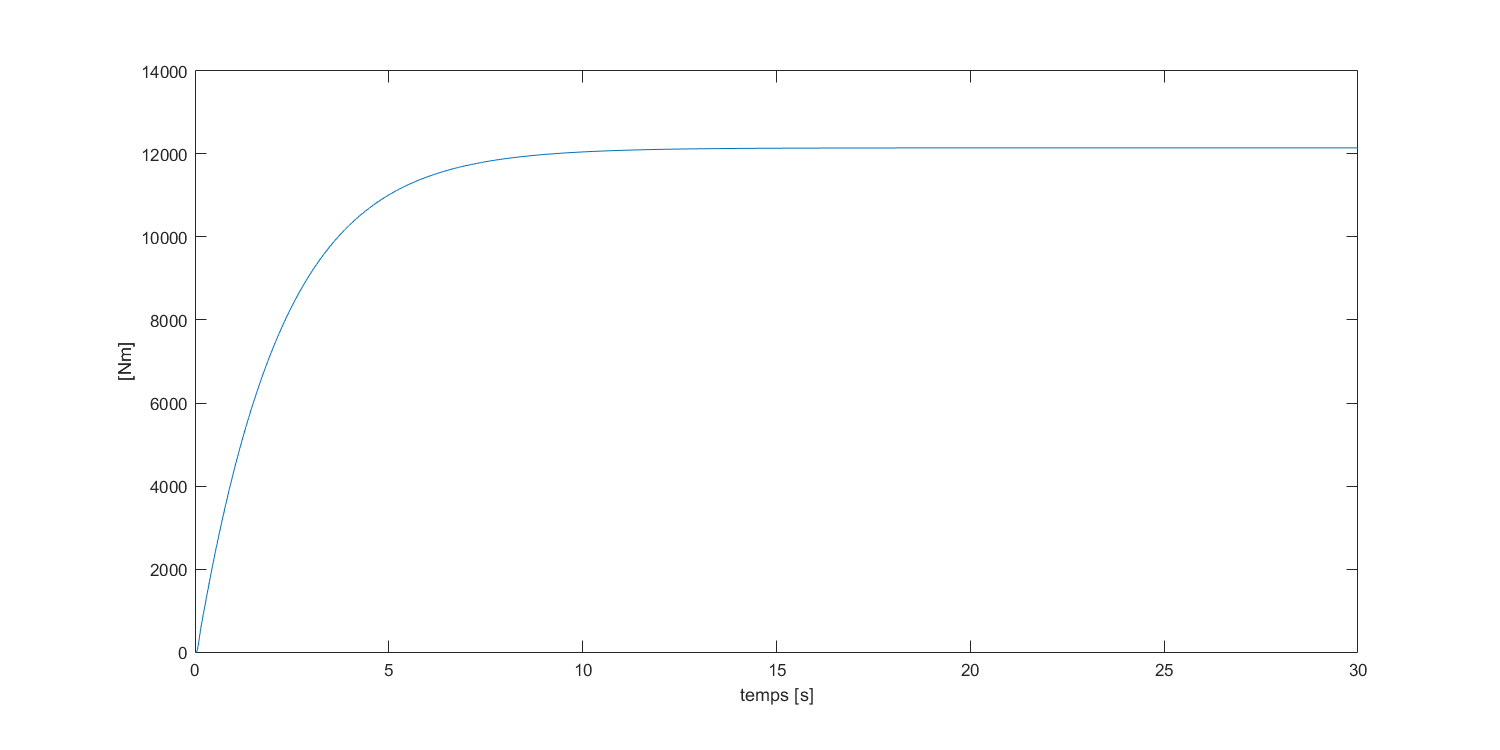

figure;
plot(t,torque); 
xlabel("temps [s]");
ylabel("[Nm]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'torque.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### courrants triphasées du rotor

ir_abc = ans.ir_abc;

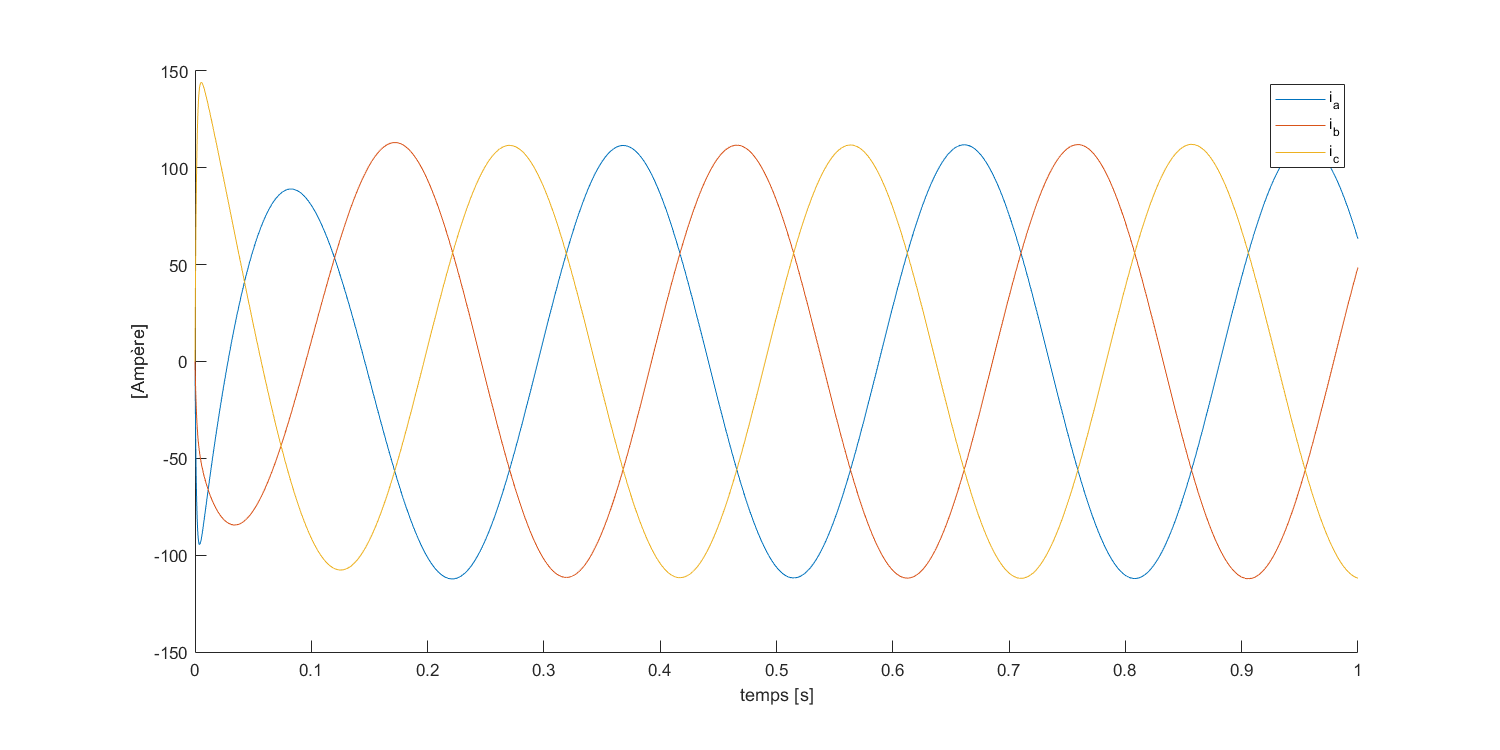

figure;
hold on;
plot(t(1:1e4),ir_abc(1:1e4,1), 'DisplayName', 'i_a'); 
plot(t(1:1e4),ir_abc(1:1e4,2), 'DisplayName', 'i_b'); 
plot(t(1:1e4),ir_abc(1:1e4,3), 'DisplayName', 'i_c'); 
legend();
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'ir_abc.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### couple de la machine

Ce = ans.Ce;

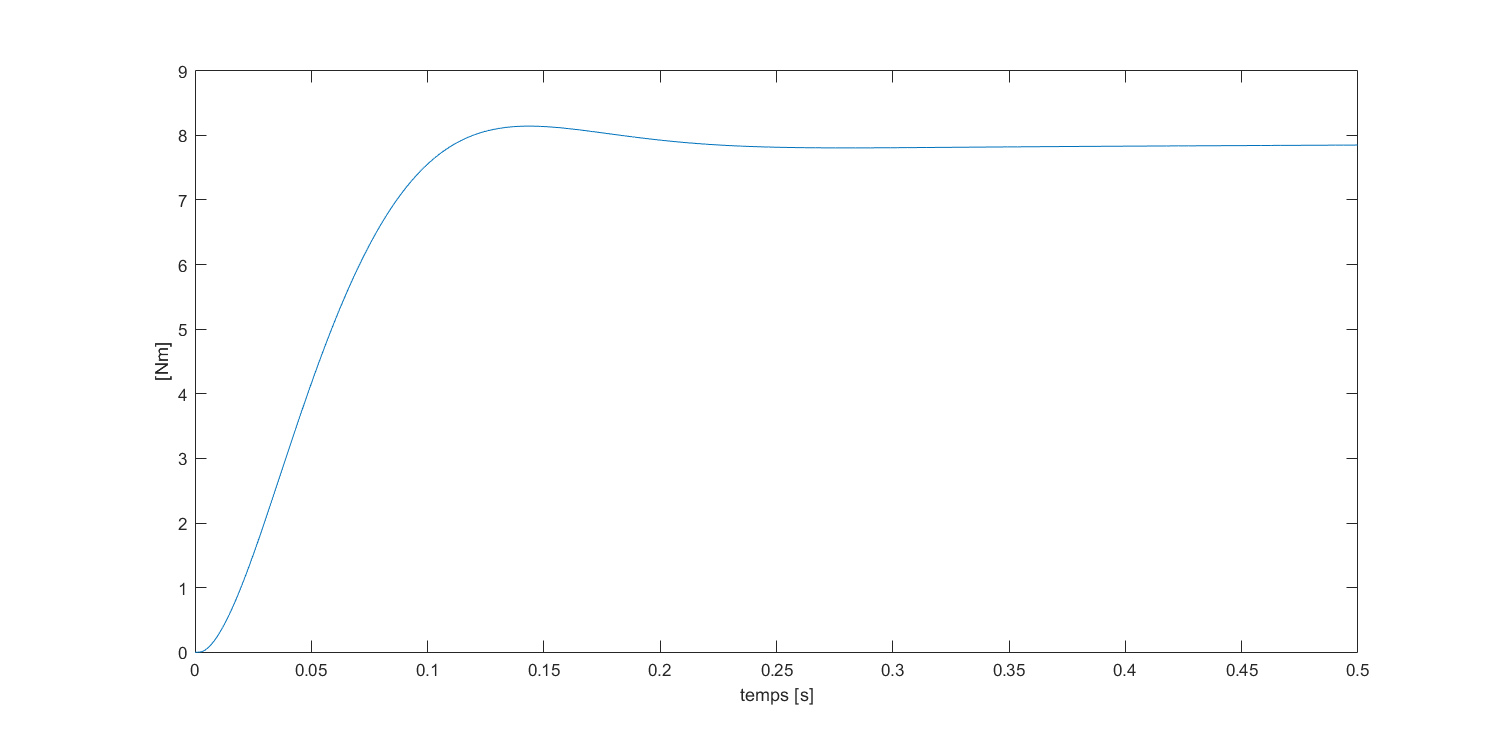

figure;
plot(t(1:1e4/2),Ce(1:1e4/2)); 
xlabel("temps [s]");
ylabel("[Nm]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'Ce.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### tensions abc du stator

vs_abc = ans.vs_abc;

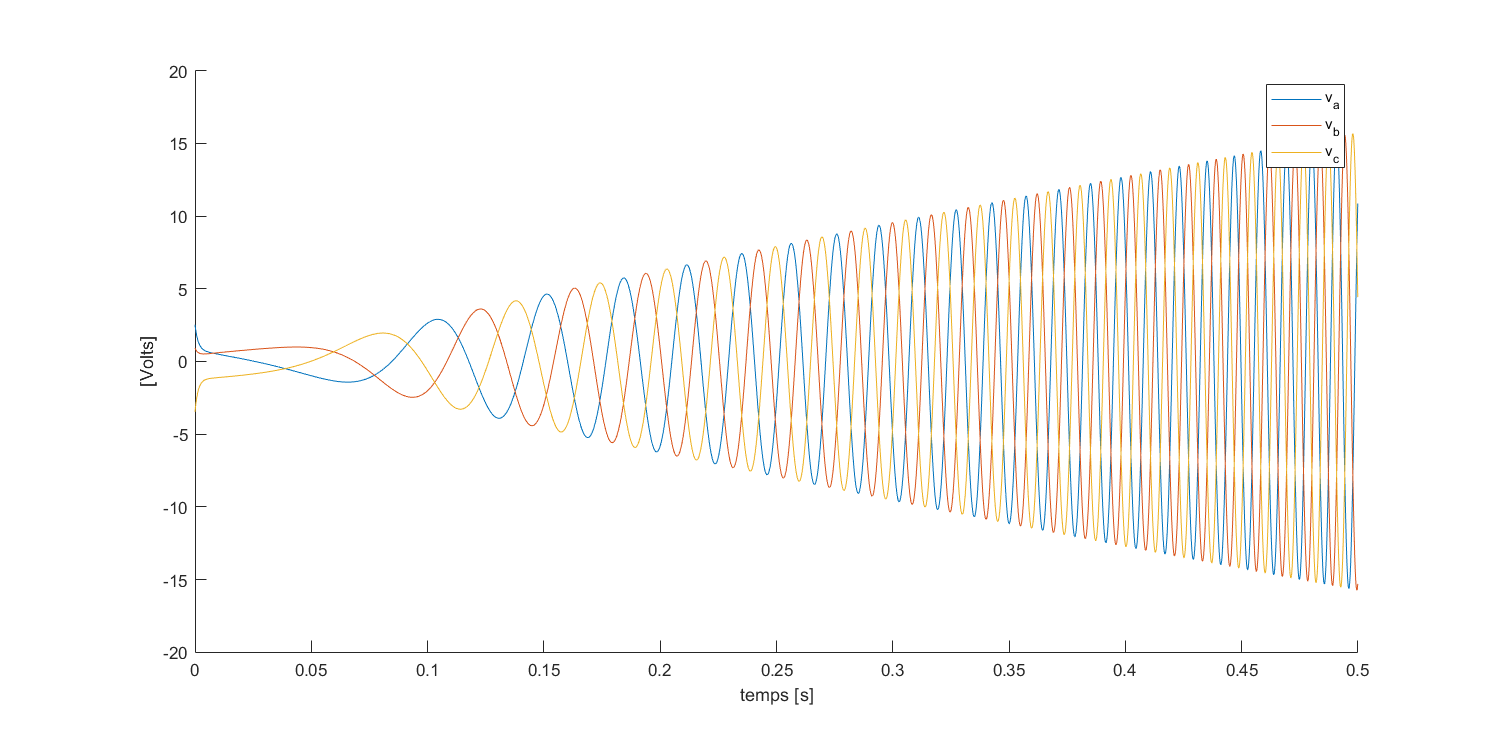

figure;
hold on;
plot(t(1:1e4/2),vs_abc(1:1e4/2,1), 'DisplayName', 'v_a'); 
plot(t(1:1e4/2),vs_abc(1:1e4/2,2), 'DisplayName', 'v_b'); 
plot(t(1:1e4/2),vs_abc(1:1e4/2,3), 'DisplayName', 'v_c'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'vs_abc.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### tensions dq du stator

vs_dq = ans.vs_dq;

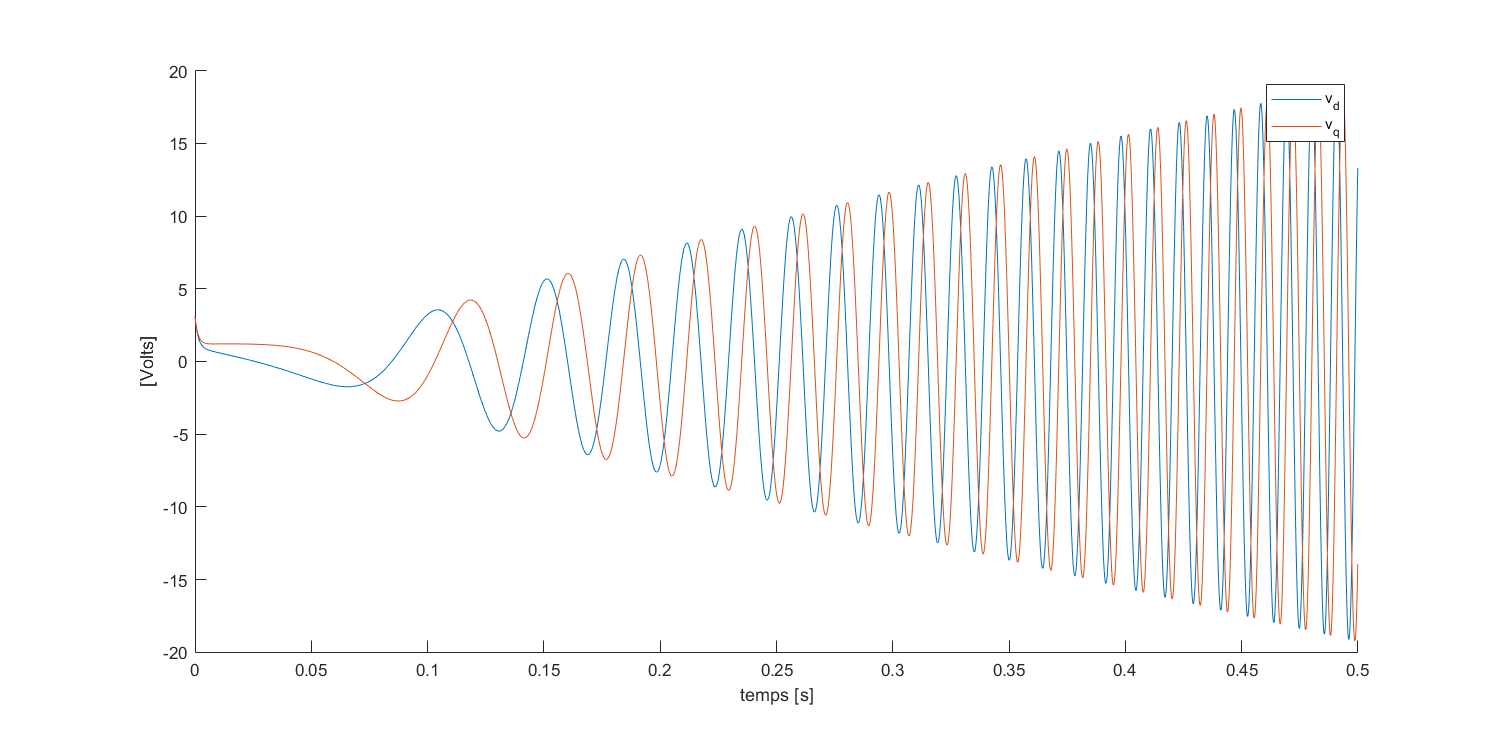

figure;
hold on;
plot(t(1:1e4/2),vs_dq(1:1e4/2,1), 'DisplayName', 'v_d'); 
plot(t(1:1e4/2),vs_dq(1:1e4/2,2), 'DisplayName', 'v_q'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'vs_dq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### tensions alpha beta du stator

Vs_alphabeta = ans.Vs_alphabeta;

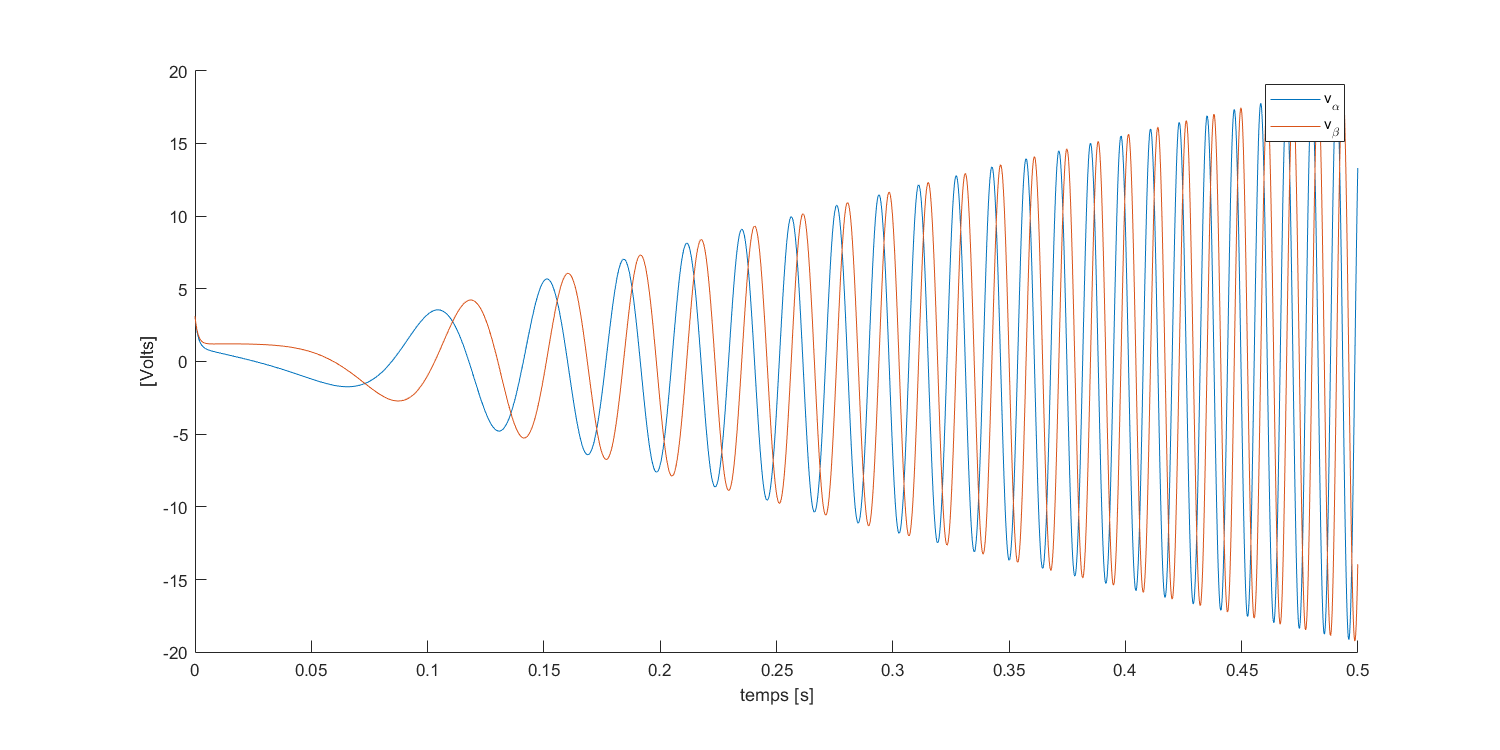

figure;
hold on;
plot(t(1:1e4/2),Vs_alphabeta(1:1e4/2,1), 'DisplayName', 'v_\alpha'); 
plot(t(1:1e4/2),Vs_alphabeta(1:1e4/2,2), 'DisplayName', 'v_\beta'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'Vs_alphabeta.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### tensions controlées par le controlateur

Vs_dq = ans.Vs_dq;

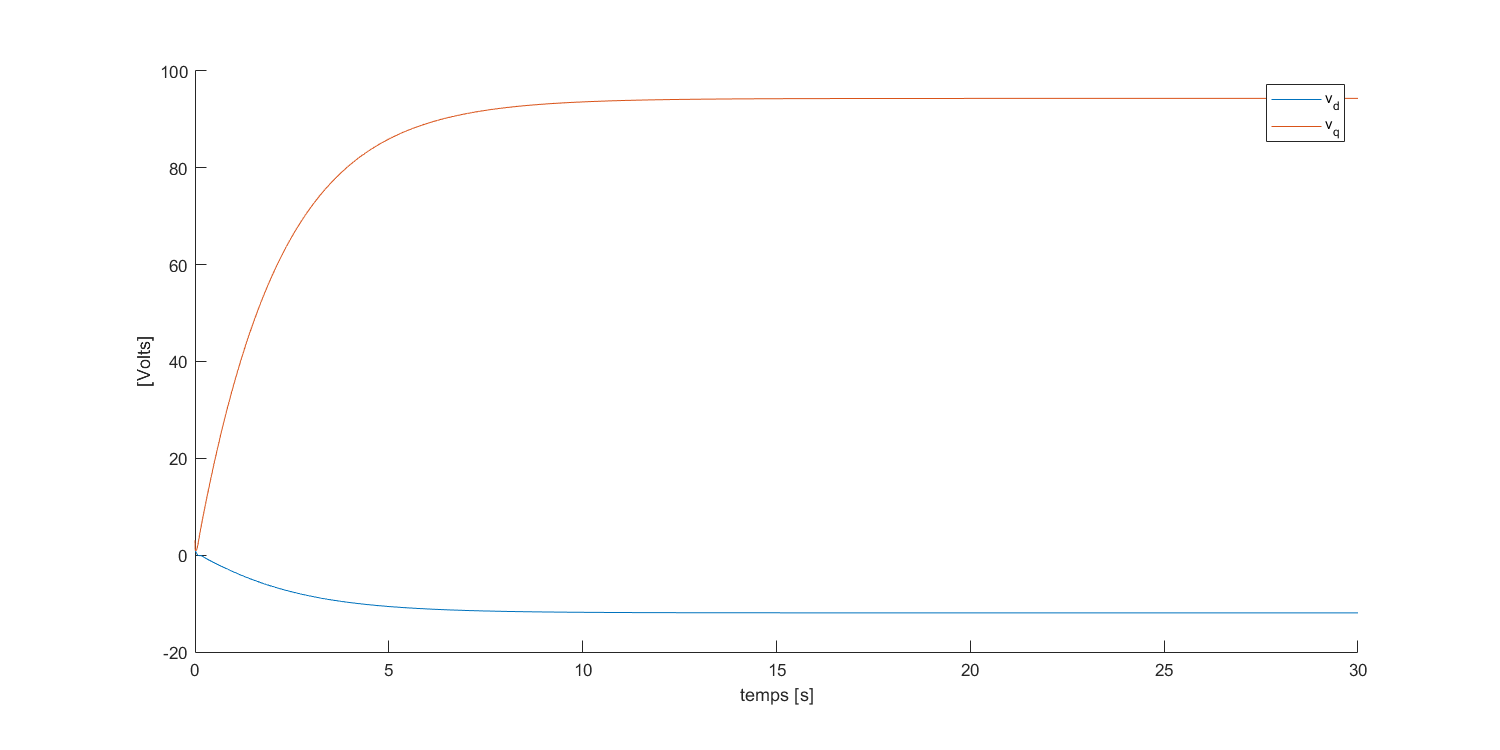

figure;
hold on;
plot(t,Vs_dq(:,1), 'DisplayName', 'v_d'); 
plot(t,Vs_dq(:,2), 'DisplayName', 'v_q'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'Vs_dq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### vérifier rélation 1 :  $w_m = \frac{C_e}{f}$ 

comparation_wm = ans.comparation_wm;

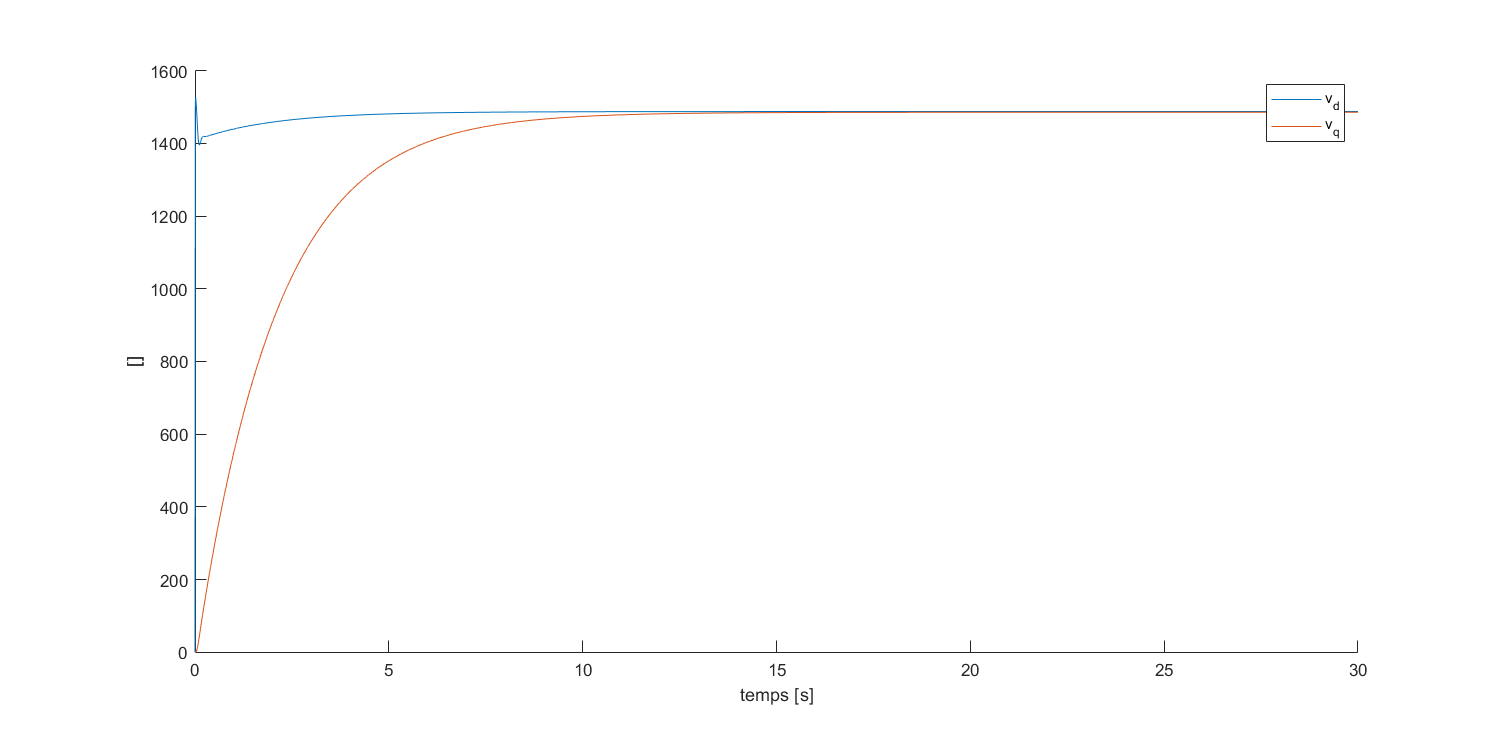

figure;
hold on;
plot(t,comparation_wm(:,1), 'DisplayName', 'v_d'); 
plot(t,comparation_wm(:,2), 'DisplayName', 'v_q'); 
legend();
xlabel("temps [s]");
ylabel("[]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'comparation_wm.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### courants dq du rotor

ir_dq = ans.ir_dq;

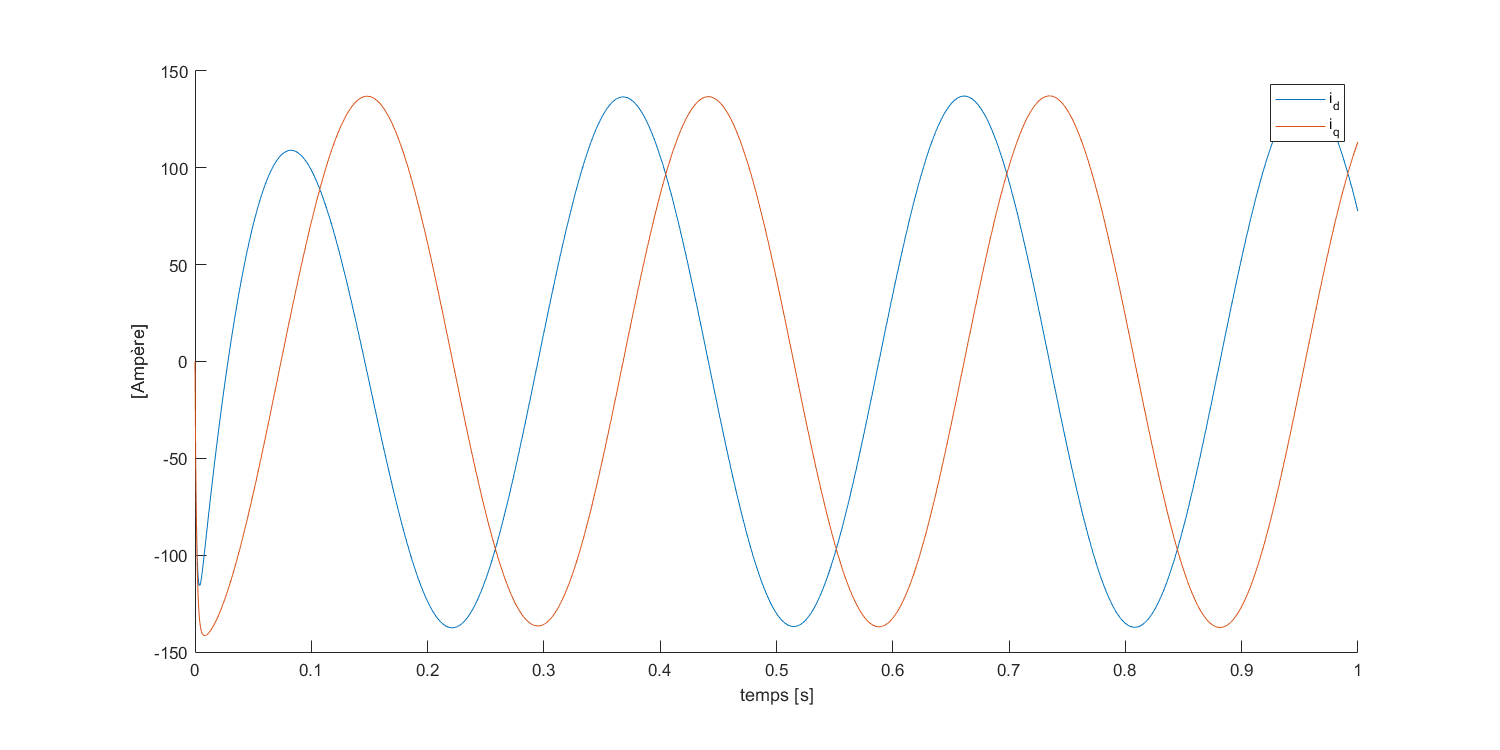

figure;
hold on;
plot(t(1:1e4),ir_dq(1:1e4,1), 'DisplayName', 'i_d'); 
plot(t(1:1e4),ir_dq(1:1e4,2), 'DisplayName', 'i_q'); 
legend();
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'ir_dq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### courants alpha beta du stator

is_alphabeta = ans.is_alphabeta;

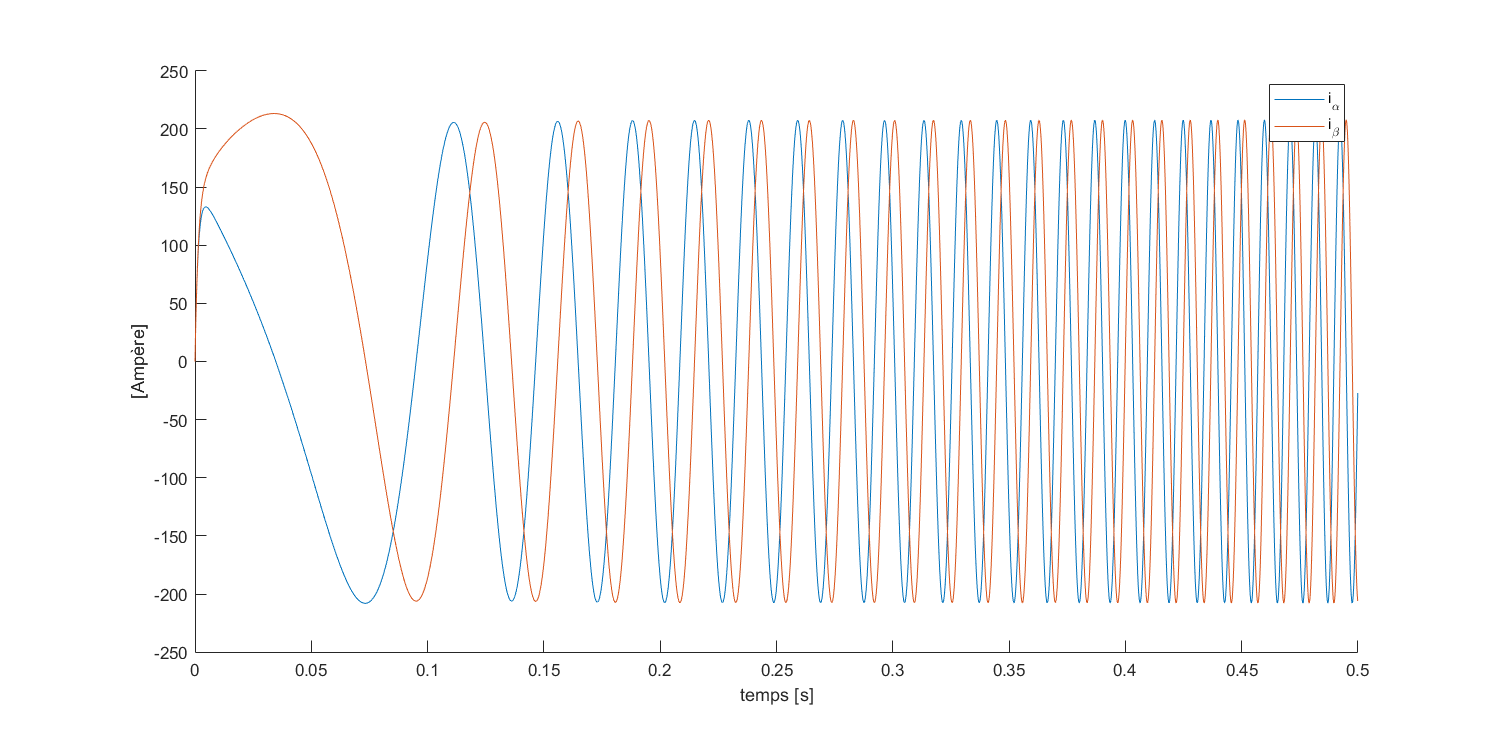

figure;
hold on;
plot(t(1:1e4/2),is_alphabeta(1:1e4/2,1), 'DisplayName', 'i_\alpha'); 
plot(t(1:1e4/2),is_alphabeta(1:1e4/2,2), 'DisplayName', 'i_\beta'); 
legend();
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'is_alphabeta.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### courants dq du stator

is_dq = ans.is_dq;

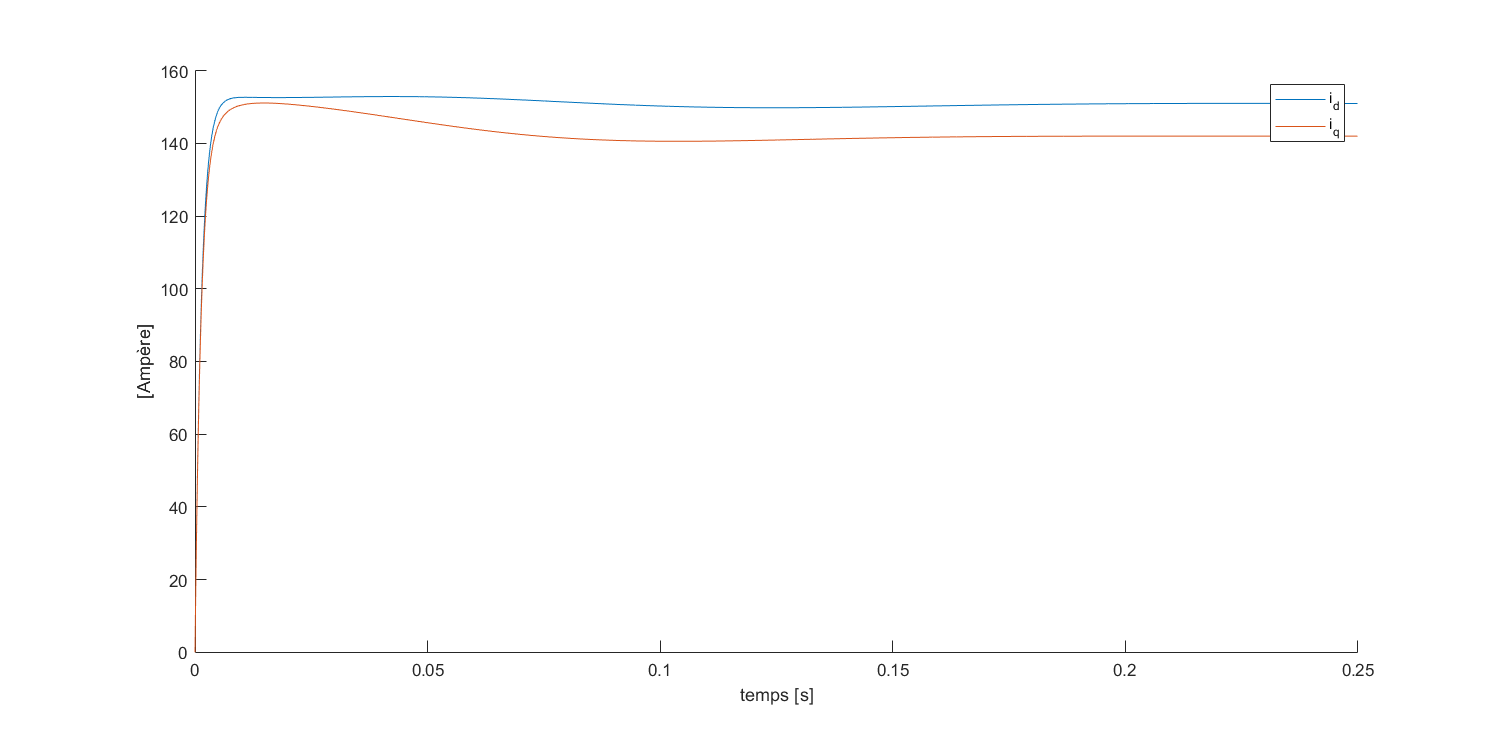

figure;
hold on;
plot(t(1:1e4/4),is_dq(1:1e4/4,1), 'DisplayName', 'i_d'); 
plot(t(1:1e4/4),is_dq(1:1e4/4,2), 'DisplayName', 'i_q'); 
legend();
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'is_dq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### flux du rotor

phi_r = ans.phi_r;

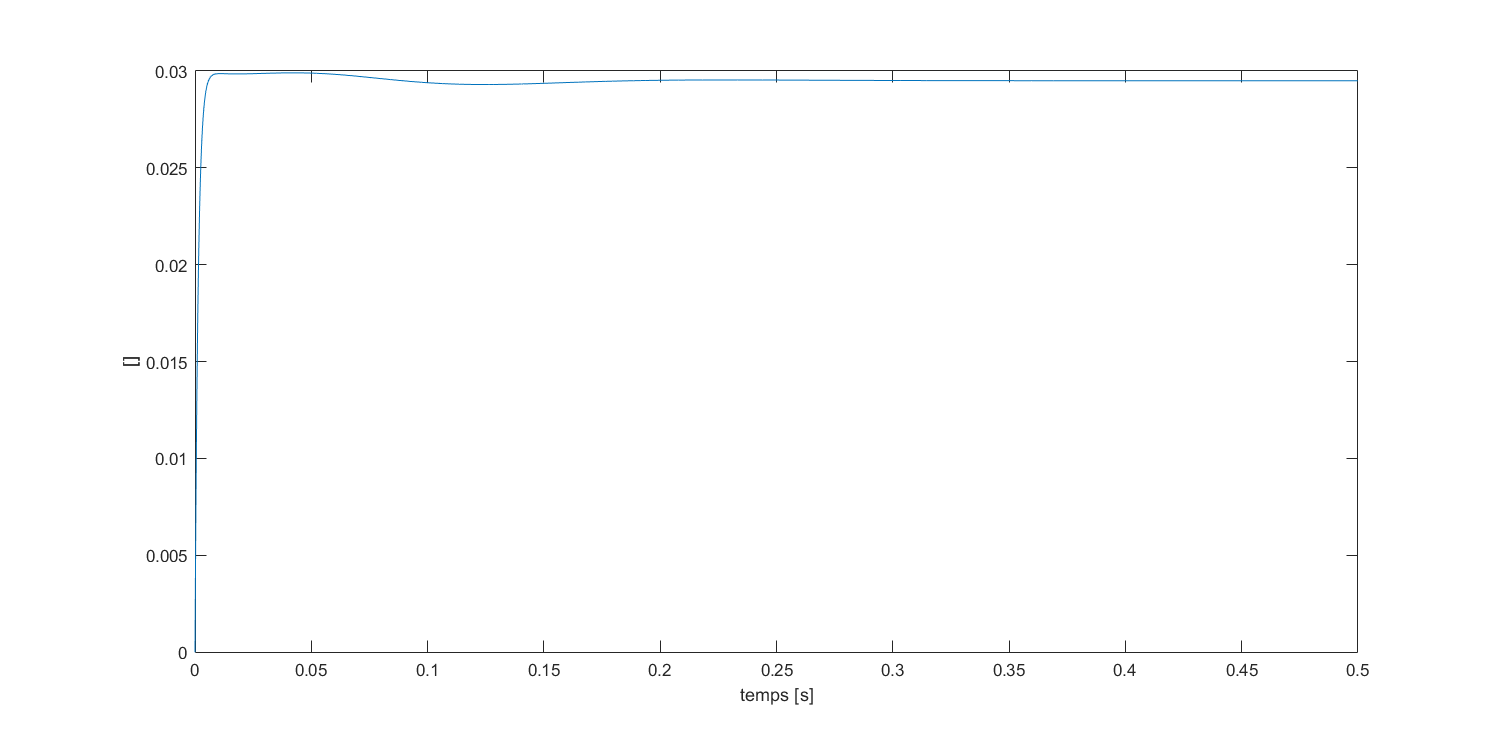

figure;
plot(t(1:1e4/2),phi_r(1:1e4/2)); 
xlabel("temps [s]");
ylabel("[Wb]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'phi_r.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### vérifier rélation 2 : $J \frac{d \Omega}{dt} = C_e - C_{load}$

relation = ans.relation;

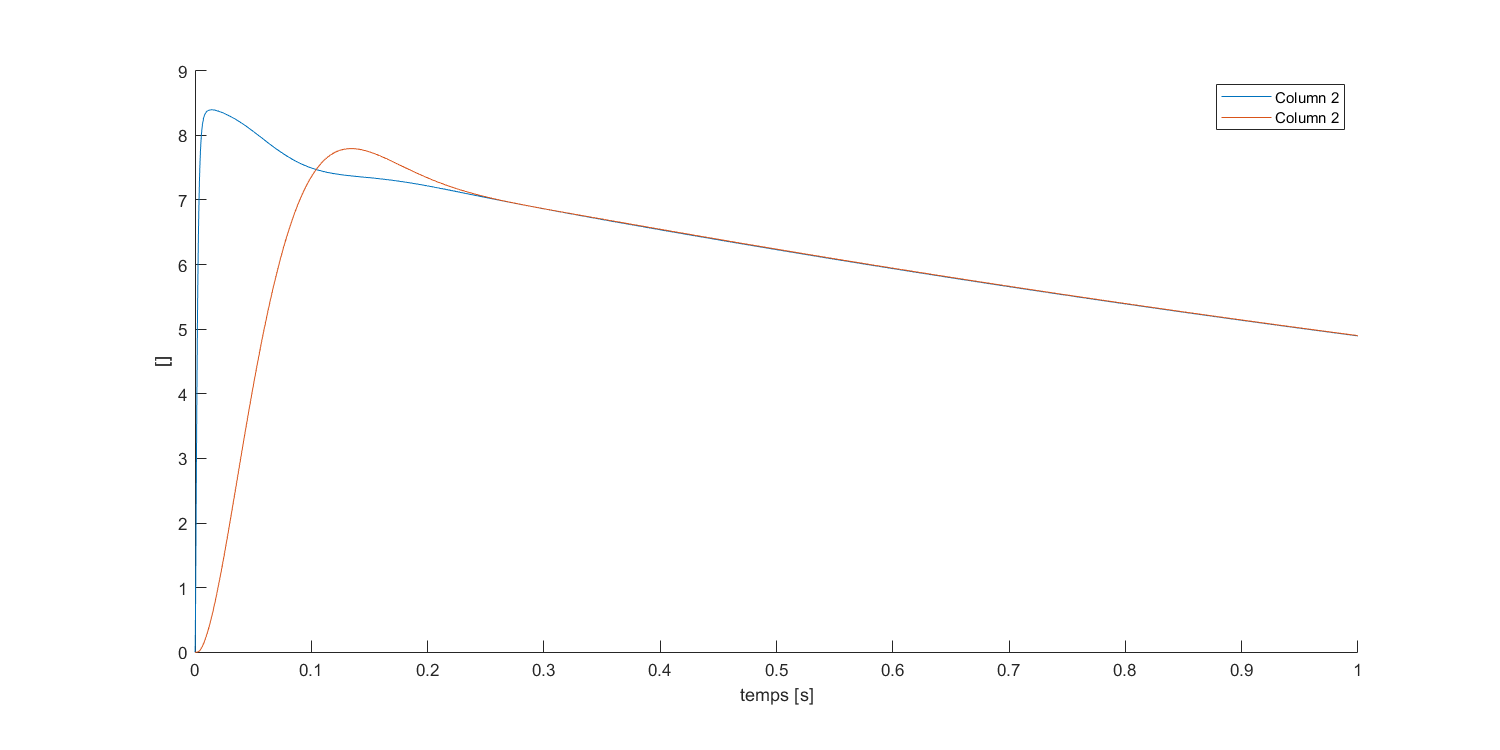

figure;
hold on;
plot(t(1:1e4),relation(1:1e4,1), 'DisplayName', 'Column 2'); 
plot(t(1:1e4),relation(1:1e4,2), 'DisplayName', 'Column 2'); 
legend();
xlabel("temps [s]");
ylabel("[]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'relation.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### angles thetas

theta = ans.theta;

theta_r = ans.theta_r;

theta_s = ans.theta_s;

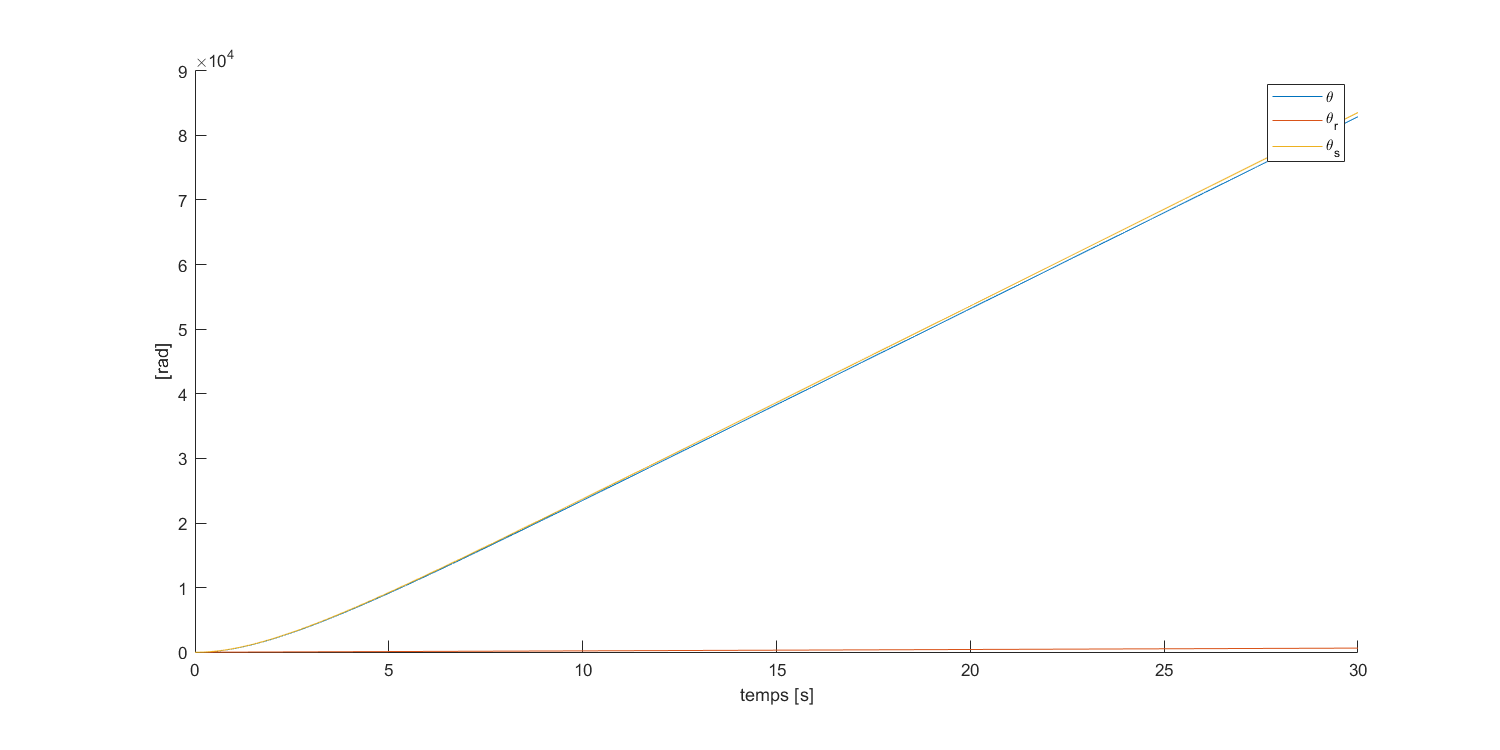

figure;
hold on;
plot(t,theta, 'DisplayName', '\theta'); 
plot(t,theta_r, 'DisplayName', '\theta_r'); 
plot(t,theta_s, 'DisplayName', '\theta_s'); 
legend();
xlabel("temps [s]");
ylabel("[rad]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'thetas.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 